clear;

N = 160;
taum = 3.5;
g = 1.5;
omega0 = 1.0;
z = 0.001;

% Theoretical sync. frequency
mu = 1 / taum;
p = [1 -omega0 mu^2+g*mu -omega0*mu^2];
eqOmegas = roots(p).';

% Keep the real root (if any)
for k=1:numel(eqOmegas)
    if isreal(eqOmegas(k))
        Omega = real(eqOmegas(k));
    end
end

% Solve expected eigenvalues
q1 = 1;
q2 = 2*mu + g*mu^2/(mu^2+Omega^2);
q3 = (mu^2 + Omega^2) + 2*g*mu^3/(mu^2 + Omega^2) - g*mu;
q = [q1 q2 q3];
eigenvalues = roots(q);

% Means and variances
mu_0 = mu^2 / (mu^2 + Omega^2);
mu2_0 = 0.5*mu*(mu/(4*Omega^2 + mu^2) + 1/mu);

mu_z = mu*(z + mu) / ((mu + z)^2 + Omega^2);
mu2_z = 0.5*mu*((2*z + mu) / (4*Omega^2 + (2*z + mu)^2) + 1/(2*z + mu));

beta = - g / (z + g*mu_0);

% DETERMINANT
MEAN = 1 + beta*mu_z;

D = eye(N);

n_trials = 1500;
arrDet = zeros(n_trials,1);
arrDet2 = zeros(n_trials,1);
errDet = zeros(n_trials,1);
arrAvg = zeros(n_trials,1);
arrVar = zeros(n_trials,1);
arrAvgexp = zeros(n_trials,1);

for i=1:n_trials
    tau0 = exprnd(taum, N);
    X = cos(Omega*tau0).*exp(-z*tau0);
    arrDiag = z + g*sum(cos(Omega*tau0),2)/N;
    Xm = z + g*repmat(sum(cos(Omega*tau0),2),1,N)/N;
    Y = diag(arrDiag) - g*X/N;
    AVG = mean(arrDiag - z, 'all');
    Y2 = D - g*(X/N) / (z + g*mu_0);
    arrAvg(i) = AVG;
    arrAvgexp(i) = mean(X, 'all');
    arrVar(i) = var(X(:));
    % arrDet(i) = det(Y) / (z + AVG)^N;
    arrDet(i) = det(Y2);
    arrDet2(i) = det(D - g*X ./ Xm/N);
end

CosExpStd = sqrt(mean(arrVar));
CosMean = mean(arrAvg/g);
CosExpMean = mean(arrAvgexp);

% DISPLAY STATUS:
disp('Expected eigenvalues:');

Expected eigenvalues:


disp(eigenvalues);

   -1.2505
   -0.1562



disp('-----------');

-----------


% disp(MEAN); MEAN < VAR => LOSS OF STABILITY POSSIBLE
disp(['Det mean = ' num2str(MEAN)]);

Det mean = 0.0015986


disp(['Det 2nd moment = ' num2str(mu2_z)]);

Det 2nd moment = 0.61649


disp('-----------');

-----------


disp(['Scaled mean = ' num2str(MEAN)]);

Scaled mean = 0.0015986


disp(['Scaled 2nd moment = ' num2str(1 + beta^2*mu2_z / N)]);

Scaled 2nd moment = 1.0124


disp(['Scaled variance = ' num2str(beta^2*mu2_z / N - beta*mu_z - beta^2*mu_z^2)]);

Scaled variance = 0.013991


disp('-----------');

-----------


disp(['cosexp std = ' num2str(CosExpStd)]);

cosexp std = 0.55382


disp(['cos mean = ' num2str(CosMean)]);

cos mean = 0.55678


disp(['cosexp mean = ' num2str(CosExpMean)]);

cosexp mean = 0.55655


disp('-----------');

-----------


disp(['g*cosexp / (z + g*cos) = ' num2str(g*CosExpMean / (z + g*CosMean))]);

g*cosexp / (z + g*cos) = 0.9984


disp(['g*cosexp std / (z + g*cos) = ' num2str(g*CosExpStd / (z + g*CosMean))]);

g*cosexp std / (z + g*cos) = 0.99351


disp('-----------');

-----------


disp(mean(arrDet)^2);

   3.1764e-06



disp(var(arrDet));

   3.9549e-05



disp('-----------');

-----------


disp(mean(arrDet2));

    0.0016



disp(var(arrDet2));

   1.7816e-08



disp('-----------');

-----------


[h,p,k,c] = lillietest(log(abs(arrDet)));

disp(p);

   1.0000e-03



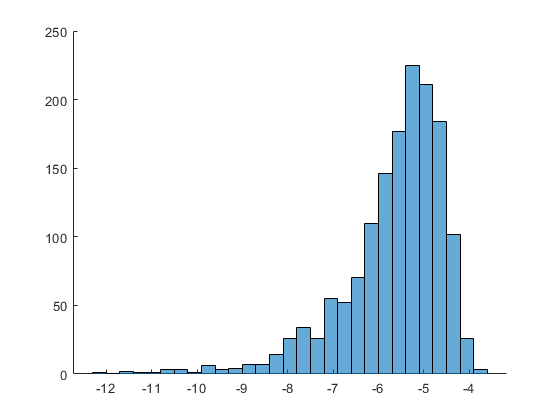


figure;
hold on;
histogram(log(abs(arrDet)))